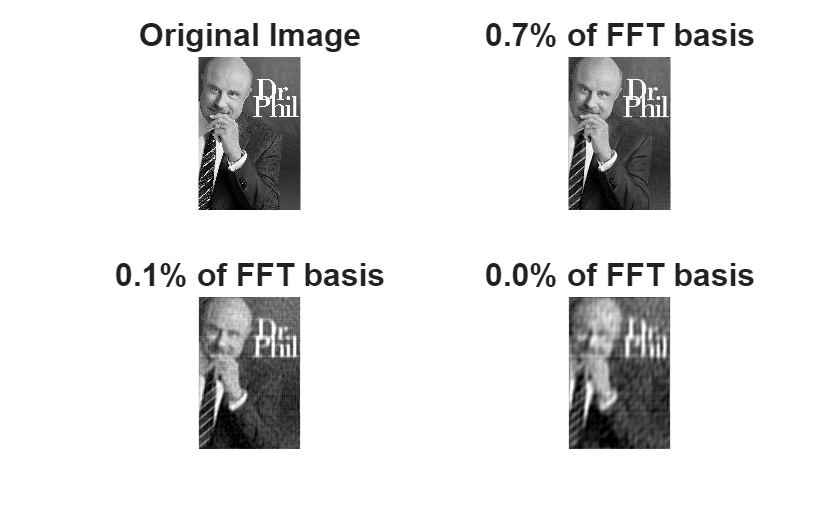

clear all; close all; clc

% Load grayscale version
A = imread("DrPhil.jpg");
A = rgb2gray(A);
[nx,ny] = size(A);

figure(1)
subplot(2,2,1), imshow(A)
title("Original Image","FontSize",16)

% 2D FFT
Ahat = fft2(A);

% Thresholds
thresh_list = 0.8 * [0.001 0.005 0.01] * max(abs(Ahat(:)));
subplot_index = 2;

for thresh = thresh_list
    mask = abs(Ahat) > thresh;
    Ahat_low = Ahat .* mask;

    percent_kept = 100 * nnz(mask) / numel(mask);
    A_low = uint8(ifft2(Ahat_low));

    subplot(2,2,subplot_index), imshow(A_low)
    title(sprintf("%.1f%% of FFT basis", percent_kept), "FontSize", 16)
    subplot_index = subplot_index + 1;
end